
csv=readtable('g_edges.csv')

csv = 549×4 table
         Source           Target       Weight    Season
    ________________    ___________    ______    ______

    {'NED'         }    {'ROBERT' }     192        1   
    {'DAENERYS'    }    {'JORAH'  }     154        1   
    {'JON'         }    {'SAM'    }     121        1   
    {'LITTLEFINGER'}    {'NED'    }     107        1   
    {'NED'         }    {'VARYS'  }      96        1   
    {'DAENERYS'    }    {'DROGO'  }      91        1   
    {'ARYA'        }    {'NED'    }      90        1   
    {'CATELYN'     }    {'ROBB'   }      90        1   
    {'BRONN'       }    {'TYRION' }      86        1   
    {'CERSEI'      }    {'NED'    }      86        1   
    {'CERSEI'      }    {'ROBERT' }      80        1   
    {'LITTLEFINGER'}    {'VARYS'  }      73        1   
    {'SHAE'        }    {'TYRION' }      73        1   
    {

G=digraph(csv.Source,csv.Target,csv.Weight)

G =   digraph with properties:

    Edges: [549×2 table]
    Nodes: [126×1 table]


p=plot(G,'layout','force')

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


deg=indegree(G)

deg =     34
    28
     1
     6
    12
    12
    11
    20
     3
     0



p.MarkerSize=2*sqrt(deg-min(deg)+0.2)

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: [1×126 double]
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


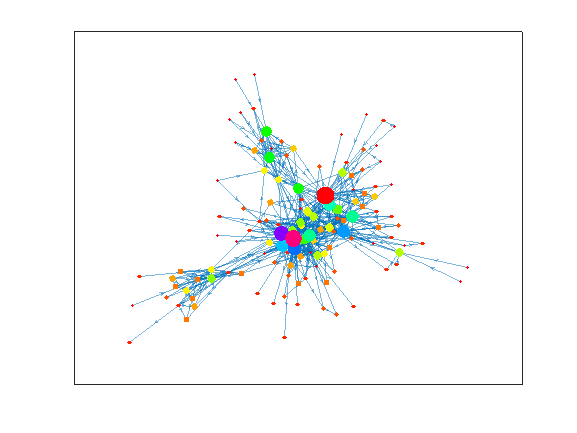


G.Nodes.NodeColors=deg;
p.NodeCData=G.Nodes.NodeColors;
colormap("hsv")



S=G.Nodes

S = 126×2 table
          Name          NodeColors
    ________________    __________

    {'NED'         }        34    
    {'ROBERT'      }        28    
    {'DAENERYS'    }         1    
    {'JORAH'       }         6    
    {'JON'         }        12    
    {'SAM'         }        12    
    {'LITTLEFINGER'}        11    
    {'VARYS'       }        20    
    {'DROGO'       }         3    
    {'ARYA'        }         0    
    {'CATELYN'     }         7    
    {'ROBB'        }        21    
    {'BRONN'       }         0    
    {'TYRION'      }        37    
    {'CERSEI'      }         6    
    {'SHAE'        }         1    


S=sortrows(S,'NodeColors','descend')

S = 126×2 table
          Name          NodeColors
    ________________    __________

    {'TYRION'      }        37    
    {'NED'         }        34    
    {'ROBERT'      }        28    
    {'SANSA'       }        22    
    {'ROBB'        }        21    
    {'VARYS'       }        20    
    {'TYWIN'       }        17    
    {'THEON'       }        16    
    {'YOREN'       }        16    
    {'PYP'         }        13    
    {'JON'         }        12    
    {'SAM'         }        12    
    {'LITTLEFINGER'}        11    
    {'RENLY'       }        11    
    {'RODRIK'      }        10    
    {'JOFFREY'     }         9    


head(S,5)

ans = 5×2 table
       Name       NodeColors
    __________    __________

    {'TYRION'}        37    
    {'NED'   }        34    
    {'ROBERT'}        28    
    {'SANSA' }        22    
    {'ROBB'  }        21    
